## M3P1

### Tutorial 1

load NCEP_slp_matlab_DXY.mat
whos

  Name            Size             Bytes  Class     Attributes

  DX             73x1                584  double              
  DY              1x144             1152  double              
  Xkm            73x144            84096  double              
  Ykm            73x144            84096  double              
  lat            73x144            84096  double              
  lon            73x144            84096  double              
  slp201412      73x144            84096  double              



Very low-level plot of pressure

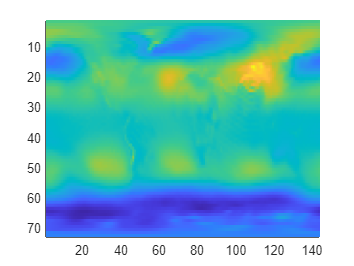

figure
pcolor(slp201412)
shading flat
axis ij

More decent plot

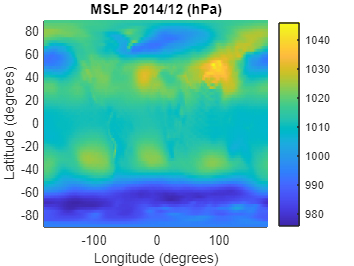

figure
pcolor(lon,lat,slp201412)
shading flat
colorbar
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')
title('MSLP 2014/12 (hPa)')

### Tutorial 2

Plotting a mathematical vector field


$$F_1 =-\frac{10y}{x^2 +y^2 }$$


x = -10:10;
y = x;
[X,Y] = meshgrid(x,y);
whos

  Name            Size             Bytes  Class     Attributes

  DX             73x1                584  double              
  DY              1x144             1152  double              
  X              21x21              3528  double              
  Xkm            73x144            84096  double              
  Y              21x21              3528  double              
  Ykm            73x144            84096  double              
  ans             1x1                  8  double              
  lat            73x144            84096  double              
  lon            73x144            84096  double              
  slp201412      73x144            84096  double              
  x               1x21               168  double              
  y               1x21               168  double              



Calculate the components of the vector field and visualize them

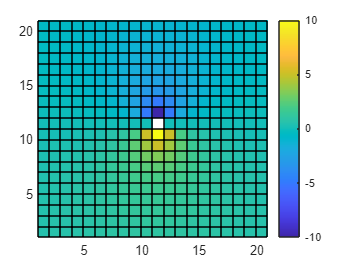

F1 = -10*Y ./ (X.^2 + Y.^2);
F2 = 8*X ./ (X.^2 + Y.^2);
figure
pcolor(F1)
colorbar

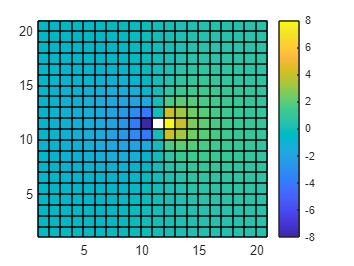

figure
pcolor(F2)
colorbar

Visualize the vectors

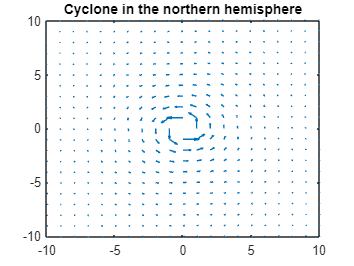

figure
quiver(X,Y,F1,F2)
title('Cyclone in the northern hemisphere')
axis tight

### Tutorial 3: distance on a sphere

DELTA = lon(1,2)-lon(1,1) % degrees

DELTA = 2.5000

figure
subplot(2,1,1)
pcolor(lon,lat,Xkm)
shading flat
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')
c = colorbar;
colorposneg
c.Label.String = 'X distance (km)'

c =   ColorBar (X distance (km)) with properties:

    Location: 'eastoutside'
      Limits: [-2.0037e+04 2.0037e+04]
    FontSize: 8.1000
    Position: [0.8190 0.5833 0.0381 0.3429]
       Units: 'normalized'

  Show all properties


clim([-20e3 20e3])

subplot(2,1,2)
pcolor(lon,lat,Ykm)
shading flat
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')
c = colorbar;
colorposneg
c.Label.String = 'Y distance (km)'

c =   ColorBar (Y distance (km)) with properties:

    Location: 'eastoutside'
      Limits: [-1.0019e+04 1.0019e+04]
    FontSize: 8.1000
    Position: [0.8190 0.1095 0.0381 0.3405]
       Units: 'normalized'

  Show all properties


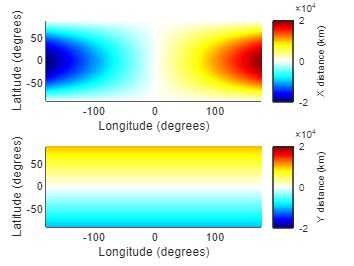

clim([-20e3 20e3])

Gradient calculation

[gx,gy] = gradient(slp201412,DELTA)

gx =     0.0129    0.0131    0.0113    0.0084    0.0056    0.0037    0.0027   -0.0006   -0.0038   -0.0044   -0.0062   -0.0092   -0.0114   -0.0147   -0.0171   -0.0171   -0.0198   -0.0214   -0.0223   -0.0250   -0.0266   -0.0270   -0.0277   -0.0297   -0.0299   -0.0300   -0.0311   -0.0319   -0.0318   -0.0339   -0.0360   -0.0351   -0.0347   -0.0378   -0.0398   -0.0406   -0.0417   -0.0417   -0.0435   -0.0460   -0.0464   -0.0465   -0.0478   -0.0473   -0.0485   -0.0492   -0.0471   -0.0465   -0.0468   -0.0452
    0.0097    0.0096    0.0079    0.0058    0.0056    0.0050    0.0026    0.0008   -0.0021   -0.0060   -0.0094   -0.0135   -0.0210   -0.0310   -0.0393   -0.0464   -0.0560   -0.0663   -0.0747   -0.0811   -0.0850   -0.0870   -0.0866   -0.0843   -0.0810   -0.0766   -0.0716   -0.0639   -0.0537   -0.0456   -0.0385   -0.0323   -0.0278   -0.0255   -0.0281   -0.0340   -0.0434   -0.0563   -0.0681   -0.0828   -0.0966   -0.1072   -0.1163   -0.1190   -0.1184   -0.1160   -0.1108   -0.1026   -0.0947   -

gy =     0.7829    0.7796    0.7759    0.7729    0.7706    0.7728    0.7732    0.7726    0.7761    0.7761    0.7729    0.7697    0.7643    0.7506    0.7316    0.7062    0.6729    0.6338    0.5832    0.5290    0.4709    0.4123    0.3509    0.2945    0.2416    0.1923    0.1484    0.1113    0.0844    0.0674    0.0610    0.0623    0.0667    0.0761    0.0913    0.0996    0.1045    0.0962    0.0755    0.0471    0.0019   -0.0532   -0.1196   -0.1902   -0.2632   -0.3300   -0.3968   -0.4574   -0.5090   -0.5532
    0.6956    0.6729    0.6530    0.6355    0.6192    0.6061    0.5902    0.5747    0.5605    0.5488    0.5371    0.5303    0.5271    0.5253    0.5278    0.5258    0.5177    0.5021    0.4704    0.4287    0.3735    0.3101    0.2421    0.1768    0.1132    0.0502   -0.0074   -0.0607   -0.1071   -0.1436   -0.1647   -0.1678   -0.1539   -0.1284   -0.0955   -0.0705   -0.0524   -0.0484   -0.0597   -0.0866   -0.1231   -0.1734   -0.2263   -0.2785   -0.3261   -0.3618   -0.3874   -0.3956   -0.3873   -

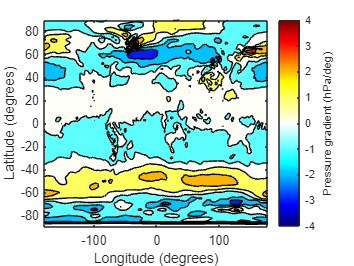

c =   ColorBar (Pressure gradient (hPa/deg)) with properties:

    Location: 'eastoutside'
      Limits: [-4 4]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8167]
       Units: 'normalized'

  Show all properties


gy = -gy; % change sign for coordinate system
figure
contourf(lon,lat,gy,-4:4)
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')
c = colorbar;
colorposneg
c.Label.String = 'Pressure gradient (hPa/deg)'

figure
pcolor(Xkm,Ykm,slp201412)
shading flat
c = colorbar;
c.Label.String = 'MSLP December 2014 (hPa)'

c =   ColorBar (MSLP December 2014 (hPa)) with properties:

    Location: 'eastoutside'
      Limits: [975.7274 1.0461e+03]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8167]
       Units: 'normalized'

  Show all properties


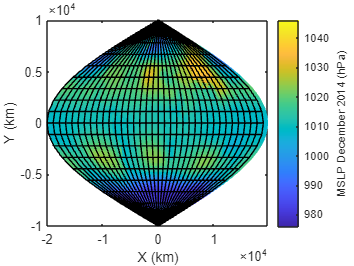

xlabel('X (km)')
ylabel('Y (km)')
hold on
plot(Xkm(1:4:end,1:4:end),Ykm(1:4:end,1:4:end),'k')
plot(Xkm(1:4:end,1:4:end)',Ykm(1:4:end,1:4:end)','k')